# **Rad229_CODE.mlx** compares both conventional (analytic) and computional optimization approaches to designing diffusion encoding gradient waveforms.

## A. Conventional (Monopolar) Diffusion Encoding Gradients

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;      % Maximum gradient amplitude [T/m]
params.smax = 100;        % Maximum slew rate [T/m/s]
params.MMT = 0;           % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;          % Diffusion b-value [s/mm^2]
params.T_readout = 0;     % Time from start to center of EPI readout [ms]
params.T_90 = 0.0;        % Duration of excitation pulse [ms]
params.T_180 = 6.0;       % Duration of refocusing pulse [ms]
params.dt = 100e-6;       % Gradient raster time for optimization [s]
tmin = 5;                 % Minimum time search [ms]
tmax = 100;               % Maximum time search [ms]

t_epi = 40;                   % We set T_readout=0 to force a monopolar solution...

G = get_min_TE_diff( params.b , tmin , tmax , params );

Unrecognized function or variable 'mex_gropt_diff_fixdt'.

Error in gropt (line 136)
        [G, lim_break] = mex_gropt_diff_fixdt(gmax, smax, moment_params, TE, T_readout, T_90, T_180, dt, diffmode, ...

Error in get_min_TE_diff (line 27)
Gc = gropt(params);

b = get_bval( G , params );

TE = length( G ) * params.dt * 1000 + t_epi / 2;
t = 1000 * ( 0 : params.dt : (length(G) - 1) * params.dt);

% Plot the gradient waveform
figure; plot(t,-G); hold on; axis([0 70 -0.1*params.gmax 1.1*params.gmax]);
  xlabel('Time [ms]'); ylabel('G(t) [T/m]');
  title(['A. MONO bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
       
% Generate the eddy current spectrum
tau_vec = [ 1 : 0.1 : 100 ];  % Range of time constants [ms]
t_eddy = 1000 * ( 0 : params.dt : ( numel(G) * params.dt ) );
ind = 1;
for k = 1 : numel( tau_vec )
  eddy_response = conv( diff(G) , exp( -t_eddy / (tau_vec(k) ) ) );
  eddy_spectrum0( ind ) = eddy_response( numel(G) );
  ind = ind + 1;
end
eddy_spectrum_max0 = max( eddy_spectrum0 );

figure; hold on;
  plot(tau_vec,eddy_spectrum0./eddy_spectrum_max0);
  title('A. Eddy Current Spectrum [\epsilon(\lambda)]');  xlabel('Time Constant (\lambda) [ms]'); ylabel('\epsilon(\lambda)[A.U.]');

## B. Convex Optimized Diffusion Encoding (CODE) Gradients

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;        % Maximum gradient amplitude [T/m]
params.smax = 100;          % Maximum slew rate [T/m/s]
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monopolar)
params.b = 1000;            % Diffusion b-value [s/mm^2]
params.T_readout = 15;      % Time from start to center of EPI readout [ms]
params.T_90 = 0;            % Duration of excitation pulse [ms]
params.T_180 = 6;           % Duration of refocusing pulse [ms]
params.dt = 100e-6;         % Gradient raster time for optimization [s]
tmin = 5;                   % Minimum time search [ms]
tmax = 100;                 % Maximum time search [ms]

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (15 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15  Done  TE = 60.800000


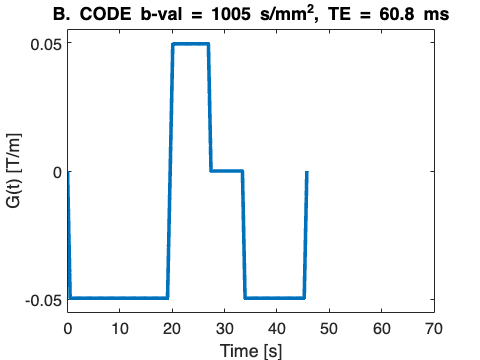

b = get_bval(G, params);
TE = length(G) * params.dt * 1000 + params.T_readout;

t = 1000 * ( 0 : params.dt : (length(G)-1) * params.dt ); %./100;
figure; plot( t , G ) ; hold on;   axis([0 70 -1.1*params.gmax 1.1*params.gmax]);
        xlabel('Time [s]'); ylabel('G(t) [T/m]'); 
        title(['B. CODE b-val = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms']);

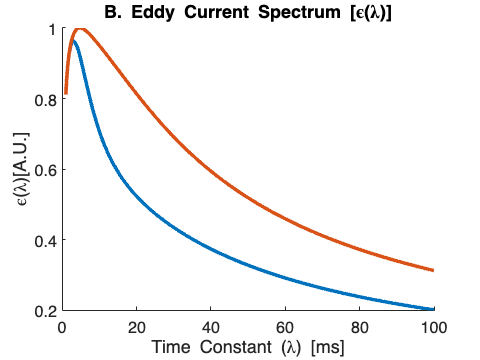


% Generate the eddy current spectrum
tau_vec=[1:0.1:100];  % Range of time constants [ms]
t_eddy=1000*(0:params.dt:(numel(G)*params.dt));
ind=1;
for k = 1:numel(tau_vec)
  eddy_response=conv(diff(G),exp(-t_eddy/(tau_vec(k))));
  eddy_spectrum(ind)=eddy_response(numel(G));
  ind=ind+1;
end

figure; hold on;
  plot(tau_vec,eddy_spectrum./eddy_spectrum_max0);
  plot(tau_vec,eddy_spectrum0./eddy_spectrum_max0);
  title('B. Eddy Current Spectrum [\epsilon(\lambda)]');  xlabel('Time Constant (\lambda) [ms]'); ylabel('\epsilon(\lambda)[A.U.]'); 

## C. Eddy current Nulled Convex Optimized Diffusion Encoding (EN-CODE) Gradients

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;        % Maximum gradient amplitude [T/m]
params.smax = 100;          % Maximum slew rate, [T/m/s]
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monopolar)
params.b = 1000;            % Diffusion b-value, [s/mm^2]
params.T_readout = 15;      % Time from start to center of EPI readout [ms]
params.T_90 = 0;            % Duration of excitation pulse [ms]
params.T_180 = 6;           % Duration of refocusing pulse [ms]
params.dt = 100e-6;         % Gradient raster time for optimization [s]
tmin = 5;                   % Minimum time search [ms]
tmax = 100;                 % Maximum time search [ms]
params.eddy_params = [];    % Eddy current compensation [time constant (ms), target, tolerance, mode]
tau = 50;                   % Eddy current time constant to null [ms]
params.eddy_params(:,end+1) = [tau , 0 , 1.0e-4 , 0];

G = get_min_TE_diff( params.b, tmin , tmax , params );

Finding TE (15 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15  Done  TE = 82.200000


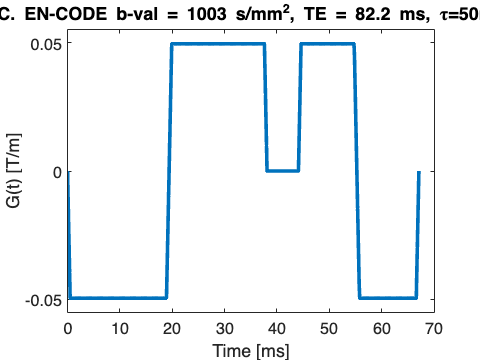

b = get_bval( G , params );
TE = length(G) * params.dt * 1000 + params.T_readout;

t = 1000 * ( 0 : params.dt : (length(G)-1) * params.dt );
figure; plot( t , G ); hold on; axis([0 70 -1.1*params.gmax 1.1*params.gmax]);
  xlabel('Time [ms]'); ylabel('G(t) [T/m]'); 
  title(['C. EN-CODE b-val = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms, \tau=',num2str(tau),'ms']);

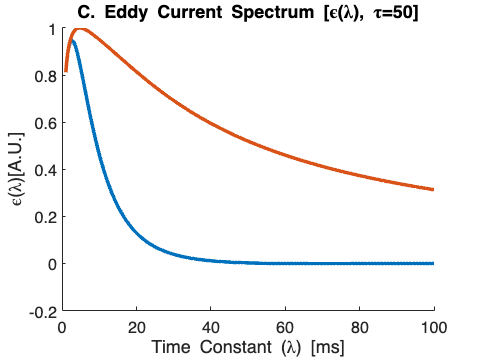

        
% Generate the eddy current spectrum
tau_vec=[ 1: 0.1 : 100 ];  % Range of time constants [ms]
t_eddy= 1000 * ( 0 : params.dt : ( numel(G) * params.dt ) );
ind=1;
for k = 1 : numel(tau_vec)
  eddy_response = conv( diff(G) , exp( -t_eddy / ( tau_vec(k) ) ) );
  eddy_spectrum(ind) = eddy_response( numel(G) );
  ind = ind + 1;
end

figure; hold on;
  plot(tau_vec,eddy_spectrum./eddy_spectrum_max0);
  plot(tau_vec,eddy_spectrum0./eddy_spectrum_max0);
  title(['C. Eddy Current Spectrum [\epsilon(\lambda), \tau=',num2str(tau),']']);  xlabel('Time Constant (\lambda) [ms]'); ylabel('\epsilon(\lambda)[A.U.]'); 

## D. PNS Response for Monopolar DWI

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;        % Maximum gradient amplitude [T/m]
params.smax = 50;          % Maximum slew rate [T/m/s]
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value [s/mm^2]
params.T_readout = 0;       % Time from start to center of EPI readout [ms]
params.T_90 = 0;            % Duration of excitation pulse [ms]
% params.T_180 = 27.6;        % Duration of refocusing pulse [ms]
params.T_180 = 6.0;        % Duration of refocusing pulse [ms]
params.dt = 100e-6;         % Gradient raster time for optimization [s]
tmin = 5;                  % Minimum time search [ms]
tmax = 100;                 % Maximum time search [ms]

t_epi = 40;                   % We set T_readout=0 to force a monopolar solution...

G = get_min_TE_diff( params.b , tmin , tmax , params );

Finding TE (15 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15  Done  TE = 43.200000


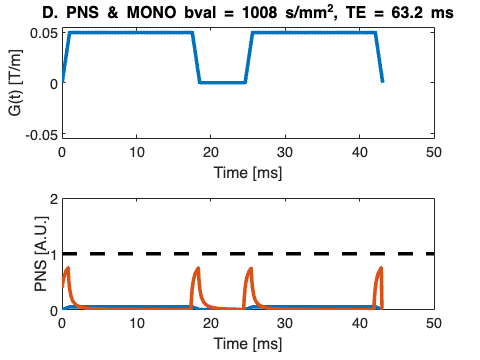

b = get_bval( G , params);
TE = length(G) * params.dt * 1000 + t_epi / 2;

PNS = abs( get_stim( G, params.dt )' );

t = 1000 * ( 0 : params.dt : (length(G)-1) * params.dt);

figure; hold on;
  subplot(2,1,1); plot(t,-G); title(['D. PNS & MONO bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
    xlabel('Time [ms]'); ylabel('G(t) [T/m]'); axis([0 50 -1.1*params.gmax 1.1*params.gmax]);
  subplot(2,1,2); plot(t,-G,t,PNS);
    xlabel('Time [ms]'); ylabel('PNS [A.U.]'); axis([0 50 0 2]);
  hline = refline([0 1.0]); hline.Color = 'k'; hline.LineStyle = '--';

## E. PNS Response for CODE DWI

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;        % Maximum gradient amplitude [T/m]
params.smax = 50;           % Maximum slew rate [T/m/s]
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value [s/mm^2]
params.T_readout = 20;      % Time from start to center of EPI readout [ms]
params.T_90 = 3;            % Duration of excitation pulse [ms]
params.T_180 = 6;           % Duration of refocusing pulse [ms]
params.dt = 100e-6;         % Gradient raster time for optimization [s]
tmin = 5;                   % Minimum time search [ms]
tmax = 100;                 % Maximum time search [ms]

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (15 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15  Done  TE = 70.000000


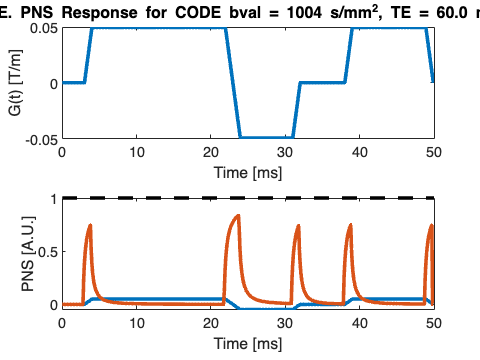

b = get_bval(G, params);
TE = length(G)*params.dt*1000 + params.T_readout/2;

PNS = abs(get_stim(G, params.dt)');

t = 1000*(0:params.dt:(length(G)-1)*params.dt);

% figure; hold on;
%   [ax]=plotyy(t,G,t,PNS);
%   title(['E. PNS & CODE bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
%   axes(ax(1)); xlabel('Time [ms]'); ylabel('G(t) [T/m]');
%   axes(ax(2)); xlabel('Time [ms]'); ylabel('PNS [A.U.]');
% 
%   xlabel('Time [s]'); ylabel('PNS [A.U.]');
%   hline = refline([0 1.0]); hline.Color = 'r'; hline.LineStyle = '--';

figure; hold on;
  subplot(2,1,1); plot(t,-G); title(['E. PNS Response for CODE bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
    xlabel('Time [ms]'); ylabel('G(t) [T/m]');
  subplot(2,1,2); plot(t,-G,t,PNS);
    xlabel('Time [ms]'); ylabel('PNS [A.U.]');
    hline = refline([0 1.0]); hline.Color = 'k'; hline.LineStyle = '--';

## F. CODE Gradients with PNS Constraint

clear params;
params.mode = 'diff_bval';
params.gmax = 50e-3;      % Maximum gradient amplitude, T/m
params.smax = 200;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
tmin = 50;                  % Minimum time search, ms
tmax = 100;                 % Maximum time search, ms
params.pns_thresh = 0.1;      % Peripheral nerve stimulation constraint (100 percent)

G2 = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (13 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13  Done  TE = 70.600000


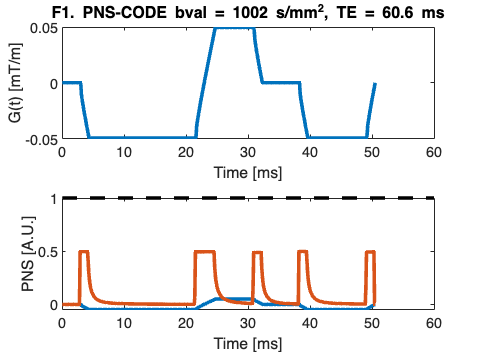

b = get_bval(G2, params);
TE = length(G2)*params.dt*1000 + params.T_readout/2;

t2 = 1000*(0:params.dt:(length(G2)-1)*params.dt);

PNS = abs(get_stim(G2, params.dt)');

% figure; hold on;
%     [ax]=plotyy(t2,G2,t2,PNS);
%     title(['F1. PNS-CODE bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
%     axes(ax(1)); xlabel('Time [ms]'); ylabel('G(t) [mT/m]');
%     axes(ax(2)); xlabel('Time [ms]'); ylabel('PNS [A.U.]');
%         hline = refline([0 1.0]); hline.Color = 'r'; hline.LineStyle = '--';

figure; hold on;
  subplot(2,1,1); plot(t2,G2); title(['F1. PNS-CODE bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
    xlabel('Time [ms]'); ylabel('G(t) [mT/m]');
  subplot(2,1,2); plot(t2,G2,t2,PNS);
    xlabel('Time [ms]'); ylabel('PNS [A.U.]');
    hline = refline([0 1.0]); hline.Color = 'k'; hline.LineStyle = '--';

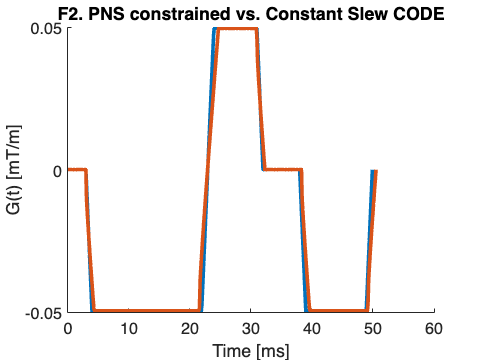

        
figure; hold on;
    plot(t,G); plot(t2,G2);
    xlabel('Time [ms]'); ylabel('G(t) [mT/m]');
    title(['F2. PNS constrained vs. Constant Slew CODE']);